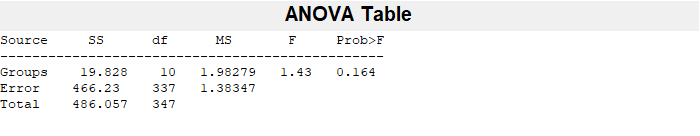

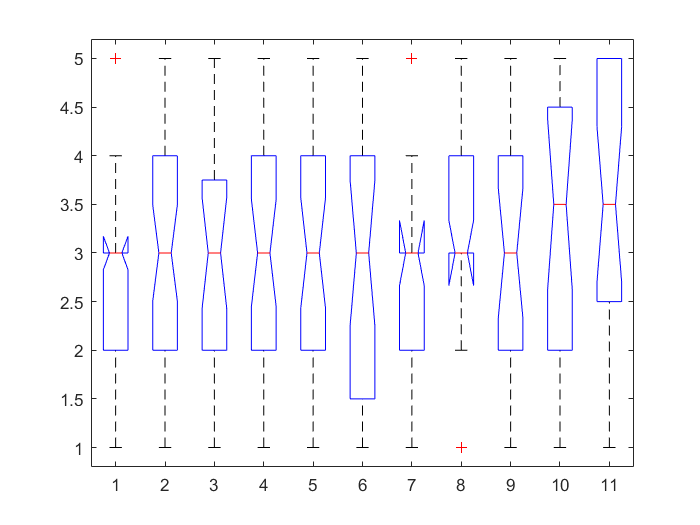

p = 0.1640


% Authorities
xlsx_name = 'C:\Users\Vellore\Documents\MATLAB\DICE\COVID_Questions_Plots_Sex_and_Lone.xlsx';
Auth = readmatrix(xlsx_name,'Sheet','Authorities','Range','B2:L84');
Auth_Sex0 = readmatrix(xlsx_name,'Sheet','Authorities Sex','Range','C2:M35');
Auth_Sex1 = readmatrix(xlsx_name,'Sheet','Authorities Sex','Range','Q2:AA49');

%{
2 tailed t test	0.848312596	mean
1 tailed t	0.424156298	mean
		
2 tailed t test	0.650477647	median
1 tailed t	0.325238824	median
%}

[list_Auth_Sex0, list_Auth_Sex1] = pulling(Auth_Sex0, Auth_Sex1);
[p] = anova1(Auth)

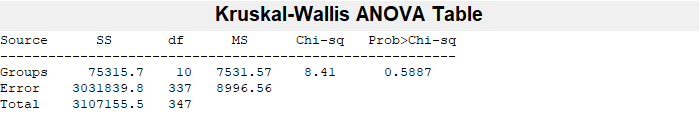

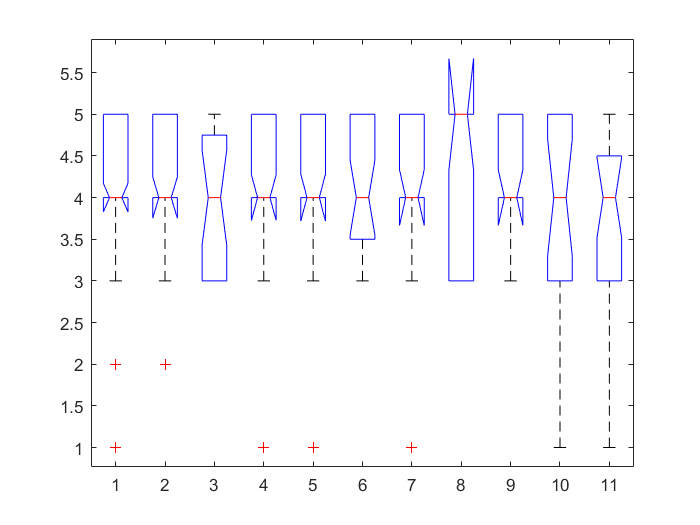

LL_kw = 0.5887


Auth = readmatrix(xlsx_name,'Sheet','Authorities','Range','B2:L84');
Auth_Lone0 = readmatrix(xlsx_name,'Sheet','Authorities Lone','Range','C2:M19');
Auth_Lone1 = readmatrix(xlsx_name,'Sheet','Authorities Lone','Range','Q2:AA66');

[list_Auth_Lone0, list_Auth_Lone1] = pulling(Auth_Lone0, Auth_Lone1);

%{
2 tailed t test	0.010316097	mean
1 tailed t	0.005158048	mean
		
2 tailed t test	0.023788015	median
1 tailed t	0.011894007	median
%}

% Last Long
LL = readmatrix(xlsx_name,'Sheet','Last Long','Range','B2:L84');
LL_Sex0 = readmatrix(xlsx_name,'Sheet','Last Long Sex','Range','C2:M35');
LL_Sex1 = readmatrix(xlsx_name,'Sheet','Last Long Sex','Range','Q2:AA49');

LL_kw = kruskalwallis(LL)

[list_LL_Sex0, list_LL_Sex1] = pulling(LL_Sex0, LL_Sex1);
[p_LL_Sex,h_LL_Sex,stats_LL_Sex] = ranksum(list_LL_Sex0,list_LL_Sex1)

p_LL_Sex = 1.5208e-04

h_LL_Sex = logical
   1


stats_LL_Sex = struct with fields:
       zval: -3.7876
    ranksum: 1.6792e+04



LL = readmatrix(xlsx_name,'Sheet','Last Long','Range','B2:L84');
LL_Lone0 = readmatrix(xlsx_name,'Sheet','Last Long Lone','Range','C2:M19');
LL_Lone1 = readmatrix(xlsx_name,'Sheet','Last Long Lone','Range','Q2:AA66');

[list_LL_Lone0, list_LL_Lone1] = pulling(LL_Lone0, LL_Lone1);
[p_LL_Lone,h_LL_Lone,stats_LL_Lone] = ranksum(list_LL_Lone0,list_LL_Lone1)

p_LL_Lone = 0.0016

h_LL_Lone = logical
   1


stats_LL_Lone = struct with fields:
       zval: 3.1554
    ranksum: 8727


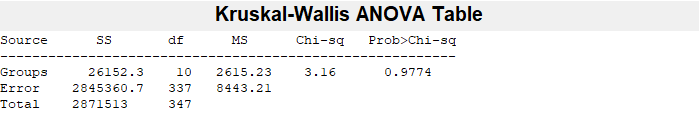

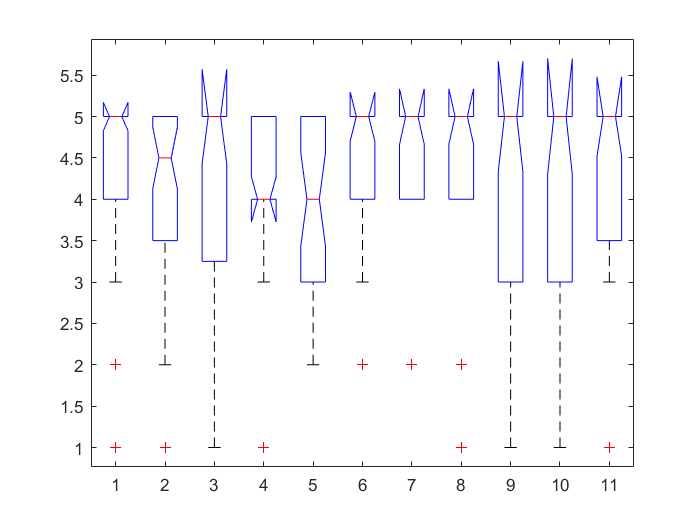

Comp_kw = 0.9774


% Compliance
Comp = readmatrix(xlsx_name,'Sheet','Compliance','Range','B2:L84');
Comp_Sex0 = readmatrix(xlsx_name,'Sheet','Compliance Sex','Range','C2:M35');
Comp_Sex1 = readmatrix(xlsx_name,'Sheet','Compliance Sex','Range','Q2:AA49');

Comp_kw = kruskalwallis(Comp)

[list_Comp_Sex0, list_Comp_Sex1] = pulling(Comp_Sex0, Comp_Sex1);
[p_Comp_Sex,h_Comp_Sex,stats_Comp_Sex] = ranksum(list_Comp_Sex0,list_Comp_Sex1)

p_Comp_Sex = 0.2630

h_Comp_Sex = logical
   0


stats_Comp_Sex = struct with fields:
       zval: -1.1194
    ranksum: 18577



Comp = readmatrix(xlsx_name,'Sheet','Compliance','Range','B2:L84');
Comp_Lone0 = readmatrix(xlsx_name,'Sheet','Compliance Lone','Range','C2:M19');
Comp_Lone1 = readmatrix(xlsx_name,'Sheet','Compliance Lone','Range','Q2:AA66');

[list_Comp_Lone0, list_Comp_Lone1] = pulling(Comp_Lone0, Comp_Lone1);
[p_Comp_Lone,h_Comp_Lone,stats_Comp_Lone] = ranksum(list_Comp_Lone0,list_Comp_Lone1)

p_Comp_Lone = 0.0522

h_Comp_Lone = logical
   0


stats_Comp_Lone = struct with fields:
       zval: -1.9416
    ranksum: 7214


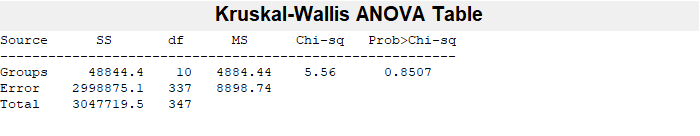

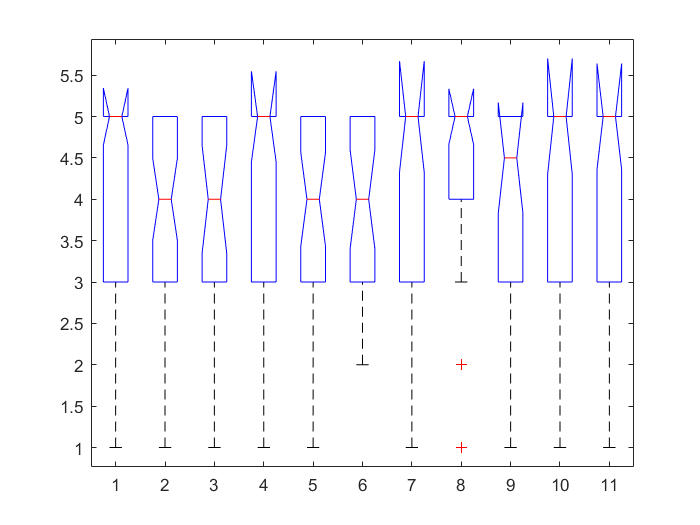

ST_kw = 0.8507


% Serious Threat
ST = readmatrix(xlsx_name,'Sheet','Serious Threat','Range','B2:L84');
ST_Sex0 = readmatrix(xlsx_name,'Sheet','Serious Threat Sex','Range','C2:M35');
ST_Sex1 = readmatrix(xlsx_name,'Sheet','Serious Threat Sex','Range','Q2:AA49');

ST_kw = kruskalwallis(ST)

[list_ST_Sex0, list_ST_Sex1] = pulling(ST_Sex0, ST_Sex1);
[p_ST_Sex,h_ST_Sex,stats_ST_Sex] = ranksum(list_ST_Sex0,list_ST_Sex1)

p_ST_Sex = 0.0027

h_ST_Sex = logical
   1


stats_ST_Sex = struct with fields:
       zval: -3.0041
    ranksum: 17303



ST_Lone0 = readmatrix(xlsx_name,'Sheet','Serious Lone','Range','C2:M19');
ST_Lone1 = readmatrix(xlsx_name,'Sheet','Serious Lone','Range','Q2:AA66');

[list_ST_Lone0, list_ST_Lone1] = pulling(ST_Lone0, ST_Lone1);
[p_ST_Lone,h_ST_Lone,stats_ST_Lone] = ranksum(list_ST_Lone0,list_ST_Lone1)

p_ST_Lone = 0.0558

h_ST_Lone = logical
   0


stats_ST_Lone = struct with fields:
       zval: -1.9129
    ranksum: 7202




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Function

function [list0, list1] = pulling(matrix0, matrix1)
    size0 = size(matrix0);
    rows = size0(1);
    cols = size0(2);
    
    list0 = [];
    i = 1;
    j = 1;
    while i < rows+1
        j = 1;
    while j <  cols+1
        list0 = [list0, matrix0(i, j)];
        j= j+1;
    end
    i= i+1;
    end

    list0 = list0(~isnan(list0));

    list1 = [];
    i = 1;
    j = 1;
    while i < rows+1
        j = 1;
    while j <  cols+1
        list1 = [list1, matrix1(i, j)];
        j= j+1;
    end
    i= i+1;
    end
    list1 = list1(~isnan(list1));
end
